clc;
clear;
close all;

%%%% getting path
% addpath(genpath('xytheta'));

% load('femm_output_sensor_r48_20220531_1937.mat')
% load('femm_output_sensor_r53_20220623_2004.mat')
% load('test.mat')
load('hi.mat')

% a1a2a3a4 b1b2b3b4 c1c2c3c4
% too many figures

% for m = x_index
%     for n = 1:1:4
%         f(n,m) = figure; %a
%         hold on;
%         legend("off")
%         legend("show",Location="best")
%         title(['x = ', num2str(x_position(1,m)),  '  sensor r=  ',num2str(sensor_r),' a',num2str(n)])
%         f(n+4,m) = figure; %b
%         hold on;
%         legend("off")
%         legend("show",Location="best")
%         title(['x = ', num2str(x_position(1,m)),  '  sensor r=  ',num2str(sensor_r),' b',num2str(n)])
%         f(n+8,m) = figure; %c
%         hold on;
%         legend("off")
%         legend("show",Location="best")
%         title(['x = ', num2str(x_position(1,m)),  '  sensor r=  ',num2str(sensor_r),' c',num2str(n)])
%     end
% end
% 
% for m = x_index
%     for n = y_index
%         figure(f(1,m));
%         plot(theta_r_in,a1(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
%         figure(f(2,m));
%         plot(theta_r_in,b1(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
%         figure(f(3,m));
%         plot(theta_r_in,c1(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
%         figure(f(4,m));
%         plot(theta_r_in,a2(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
%         figure(f(5,m));
%         plot(theta_r_in,b2(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
%         figure(f(6,m));
%         plot(theta_r_in,c2(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
%         figure(f(7,m));
%         plot(theta_r_in,a3(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
%         figure(f(8,m));
%         plot(theta_r_in,b3(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
%         figure(f(9,m));
%         plot(theta_r_in,c3(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
%         figure(f(10,m));
%         plot(theta_r_in,a4(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
%         figure(f(11,m));
%         plot(theta_r_in,b4(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
%         figure(f(12,m));
%         plot(theta_r_in,c4(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
%     end
% end

max_peak_flux = zeros(length(x_index),length(y_index));
min_peak_flux = zeros(length(x_index),length(y_index));


for x = x_index
    for y = y_index
        max_arr = [max(abs(a1(:,x,y))),max(abs(a2(:,x,y))),max(abs(a3(:,x,y))),max(abs(a4(:,x,y))), ...
            max(abs(b1(:,x,y))),max(abs(b2(:,x,y))),max(abs(b3(:,x,y))),max(abs(b4(:,x,y))) ...
            ,max(abs(c1(:,x,y))),max(abs(c2(:,x,y))),max(abs(c3(:,x,y))),max(abs(c4(:,x,y)))];
        max_peak_flux(x,y) = max(max_arr);
        min_peak_flux(x,y) = min(max_arr);
        diff = a1(:,x,y)-a2(:,x,y);
    end
end

max_peak_flux'

ans =     0.0537    0.0529    0.0521    0.0513    0.0514    0.0513    0.0521    0.0529    0.0537
    0.0529    0.0515    0.0507    0.0499    0.0498    0.0500    0.0507    0.0515    0.0529
    0.0521    0.0507    0.0494    0.0487    0.0483    0.0487    0.0494    0.0507    0.0521
    0.0513    0.0500    0.0486    0.0474    0.0469    0.0474    0.0487    0.0499    0.0514
    0.0514    0.0498    0.0483    0.0469    0.0455    0.0469    0.0483    0.0498    0.0514
    0.0514    0.0500    0.0487    0.0474    0.0469    0.0474    0.0487    0.0499    0.0513
    0.0521    0.0507    0.0494    0.0486    0.0483    0.0487    0.0494    0.0507    0.0521
    0.0529    0.0515    0.0507    0.0499    0.0498    0.0500    0.0507    0.0515    0.0529
    0.0537    0.0529    0.0521    0.0513    0.0514    0.0514    0.0521    0.0529    0.0537


min_peak_flux'

ans =     0.0388    0.0393    0.0399    0.0404    0.0404    0.0404    0.0399    0.0393    0.0387
    0.0393    0.0403    0.0409    0.0415    0.0416    0.0415    0.0409    0.0403    0.0393
    0.0399    0.0409    0.0420    0.0426    0.0429    0.0426    0.0419    0.0409    0.0399
    0.0404    0.0415    0.0426    0.0437    0.0442    0.0437    0.0426    0.0415    0.0404
    0.0404    0.0416    0.0429    0.0442    0.0455    0.0442    0.0429    0.0416    0.0404
    0.0404    0.0415    0.0426    0.0437    0.0442    0.0437    0.0426    0.0415    0.0404
    0.0399    0.0409    0.0420    0.0426    0.0429    0.0426    0.0420    0.0409    0.0399
    0.0393    0.0403    0.0409    0.0415    0.0416    0.0415    0.0409    0.0403    0.0393
    0.0388    0.0393    0.0399    0.0404    0.0404    0.0404    0.0399    0.0393    0.0387


dif_max_flux =max_peak_flux'-min_peak_flux'

dif_max_flux =     0.0149    0.0136    0.0122    0.0109    0.0109    0.0109    0.0122    0.0136    0.0150
    0.0136    0.0112    0.0098    0.0084    0.0082    0.0084    0.0098    0.0112    0.0136
    0.0122    0.0098    0.0074    0.0061    0.0055    0.0061    0.0075    0.0098    0.0122
    0.0109    0.0084    0.0061    0.0037    0.0027    0.0037    0.0061    0.0084    0.0109
    0.0109    0.0082    0.0054    0.0027    0.0000    0.0027    0.0054    0.0082    0.0109
    0.0109    0.0084    0.0061    0.0037    0.0027    0.0037    0.0061    0.0084    0.0109
    0.0122    0.0098    0.0074    0.0061    0.0054    0.0061    0.0074    0.0098    0.0122
    0.0136    0.0112    0.0098    0.0084    0.0082    0.0084    0.0098    0.0112    0.0136
    0.0149    0.0136    0.0122    0.0109    0.0109    0.0109    0.0122    0.0136    0.0150


max_flux = max(max(max_peak_flux))

max_flux = 0.0537

min_flux = min(min(min_peak_flux))

min_flux = 0.0387


fine_x= find(max_peak_flux'*25-2.5 <0,1)

fine_x = 1

x_position(fine_x)

ans = -2

dq = 2/3*[1 -0.5 -0.5;0 sqrt(3)/2 -sqrt(3)/2;1/2 1/2 1/2]

dq =     0.6667   -0.3333   -0.3333
         0    0.5774   -0.5774
    0.3333    0.3333    0.3333



alpha = zeros(4,length(theta_r_index),length(x_index),length(y_index));
beta = zeros(4,length(theta_r_index),length(x_index),length(y_index));
gamma = zeros(4,length(theta_r_index),length(x_index),length(y_index));
for(r = theta_r_index)
    for(x = x_index)
        for(y = y_index)
            alpha(1,r,x,y)=dq(1,:)*[a1(r,x,y);b1(r,x,y);c1(r,x,y)];
            alpha(2,r,x,y)=dq(1,:)*[a2(r,x,y);b2(r,x,y);c2(r,x,y)];
            alpha(3,r,x,y)=dq(1,:)*[a3(r,x,y);b3(r,x,y);c3(r,x,y)];
            alpha(4,r,x,y)=dq(1,:)*[a4(r,x,y);b4(r,x,y);c4(r,x,y)];
            beta(1,r,x,y)=dq(2,:)*[a1(r,x,y);b1(r,x,y);c1(r,x,y)];
            beta(2,r,x,y)=dq(2,:)*[a2(r,x,y);b2(r,x,y);c2(r,x,y)];
            beta(3,r,x,y)=dq(2,:)*[a3(r,x,y);b3(r,x,y);c3(r,x,y)];
            beta(4,r,x,y)=dq(2,:)*[a4(r,x,y);b4(r,x,y);c4(r,x,y)];
            gamma(1,r,x,y)=dq(3,:)*[a1(r,x,y);b1(r,x,y);c1(r,x,y)];
            gamma(2,r,x,y)=dq(3,:)*[a2(r,x,y);b2(r,x,y);c2(r,x,y)];
            gamma(3,r,x,y)=dq(3,:)*[a3(r,x,y);b3(r,x,y);c3(r,x,y)];
            gamma(4,r,x,y)=dq(3,:)*[a4(r,x,y);b4(r,x,y);c4(r,x,y)];
        end
    end
end

x12 = zeros(length(theta_r_index),length(x_index),length(y_index));
y12 = zeros(length(theta_r_index),length(x_index),length(y_index));
x34 = zeros(length(theta_r_index),length(x_index),length(y_index));
y34 = zeros(length(theta_r_index),length(x_index),length(y_index));

xhat = zeros(length(theta_r_index),length(x_index),length(y_index));
yhat = zeros(length(theta_r_index),length(x_index),length(y_index));

for(r = theta_r_index)
    for(x = x_index)
        for(y = y_index)
            x12(r,x,y) = alpha(1,r,x,y)*gamma(1,r,x,y)-alpha(2,r,x,y)*gamma(2,r,x,y);
            y12(r,x,y) = beta(1,r,x,y)*gamma(1,r,x,y)-beta(2,r,x,y)*gamma(2,r,x,y);
            x34(r,x,y) = cos(-pi/6)*(alpha(3,r,x,y)*gamma(3,r,x,y)-alpha(4,r,x,y)*gamma(4,r,x,y))-sin(-pi/6)*(beta(3,r,x,y)*gamma(3,r,x,y)-beta(4,r,x,y)*gamma(4,r,x,y));
            y34(r,x,y) = sin(-pi/6)*(alpha(3,r,x,y)*gamma(3,r,x,y)-alpha(4,r,x,y)*gamma(4,r,x,y))+cos(-pi/6)*(beta(3,r,x,y)*gamma(3,r,x,y)-beta(4,r,x,y)*gamma(4,r,x,y));

        end
    end
end



%%kg calculation x=1, y=0 fixed point
    
    x_mid = median(x_index);
    y_mid = median(y_index);
    checkx1y0 = x12(:,x_mid+1,y_mid)+x34(:,x_mid+1,y_mid);
    x1y0 = [x_position(1,x_mid+1),y_position(1,y_mid)]

x1y0 =     0.5000         0


    mean(checkx1y0);
    kg = round(norm(x1y0)/mean(checkx1y0))

kg = 3999


for r = theta_r_index
    for x = x_index
        for y = y_index
            xhat(r,x,y) = kg*(x12(r,x,y)+x34(r,x,y));
            yhat(r,x,y) = -kg*(y12(r,x,y)+y34(r,x,y));
        end
    end
end

%%theta calculation
theta1hat = zeros(length(theta_r_index),length(x_index),length(y_index));
theta2hat = zeros(length(theta_r_index),length(x_index),length(y_index));
theta_r_hat = zeros(length(theta_r_index),length(x_index),length(y_index));
% for r = theta_r_index
%     for x = x_index
%         for y = y_index
%             theta1hat(r,x,y) = atan2(beta(2,r,x,y),alpha(1,r,x,y));
%             theta2hat(r,x,y) = atan2(beta(1,r,x,y),alpha(2,r,x,y));
%             theta_r_hat(r,x,y) = (theta1hat(r,x,y)+theta2hat(r,x,y))/2;
%         end
%     end
% end

for x = x_index
    for y = y_index
            theta1hat(:,x,y) = atan2(beta(2,:,x,y),alpha(1,:,x,y));
            theta2hat(:,x,y) = atan2(beta(1,:,x,y),alpha(2,:,x,y));
            theta_r_hat(:,x,y) = (theta1hat(:,x,y)+theta2hat(:,x,y))/2;
    end
end
theta1hat(:,1,1)

ans =     0.0237
    0.0586
    0.0932
    0.1287
    0.1633
    0.1989
    0.2332
    0.2686
    0.3045
    0.3396


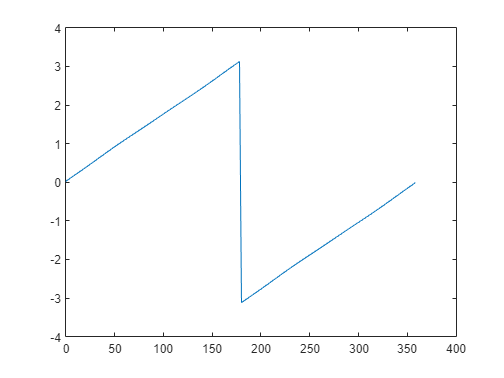

plot(theta_elec_in,theta1hat(:,1,1))

% f2 = zeros(length(x_index),2);
% 
% for m = x_index
%         f2(m,1) = figure; %a
%         hold on;
%         legend("off")
%         legend("show",Location="best")
%         title(['xhat ','x = ', num2str(x_position(1,m)),  '  sensor r=  ',num2str(sensor_r),' mm'])
% %         f2(m,2) = figure;
% %         hold on;
% %         legend("off")
% %         legend("show",Location="best")
% %         title(['yhat ','x = ', num2str(x_position(1,m)),  '  sensor r=  ',num2str(sensor_r),' mm'])
%     for n = y_index
%         figure(f2(m,1));
%         plot(theta_r_in,xhat(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
% %         figure(f2(m,2));
% %         plot(theta_r_in,yhat(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
%     end
% end

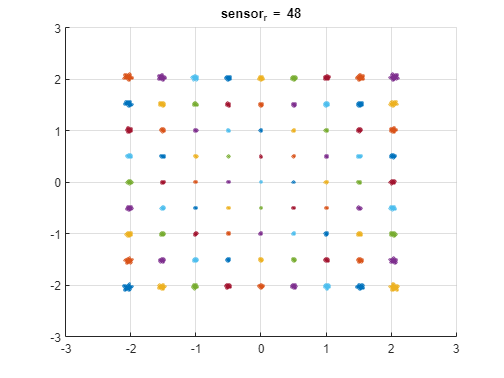

full_figure = figure;
hold on;
grid on;
title(['sensor_r = ',num2str(sensor_r)])
xlim([min(x_position)-1,max(x_position)+1])
ylim([min(y_position)-1,max(y_position)+1])
for m = x_index
    for n = y_index
        scatter(xhat(:,m,n),yhat(:,m,n),2)
    end
end


date = datestr(now,'yyyymmdd_HHMM')

date = '20220624_1115'

filename = sprintf('xytheta_output_sensor_r%d_kg%d_%s.mat',sensor_r,kg,date)

filename = 'xytheta_output_sensor_r48_kg3999_20220624_1115.mat'

% filename = 'hi2'
save(filename)